## Check points

% should add out folder to matlab path
filename = 'output_file.txt';
delimiterIn = ' ';
A = importdata(filename,delimiterIn);
X = A(:, 1);
Y = A(:, 2);
Z = A(:, 3);

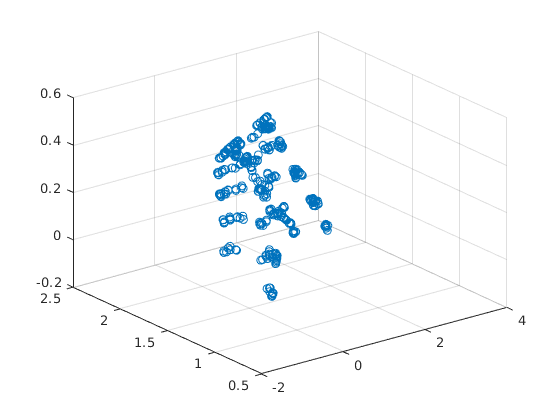

scatter3(X,Y,Z)

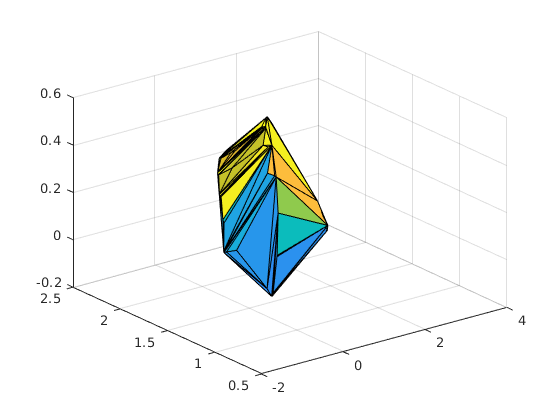

tri = delaunayTriangulation(X, Y, Z);
[C,v] = convexHull(tri);
trisurf(C, X, Y, Z)

clc;
A= roundn(A,-3);
pc = pointCloud(A);
ptCloudOut = pcdownsample(pc,'gridAverage',0.1)

ptCloudOut =   pointCloud with properties:

     Location: [107×3 double]
        Color: [0×3 uint8]
       Normal: [0×3 double]
    Intensity: []
        Count: 107
      XLimits: [-1.0158 3.1655]
      YLimits: [0.8251 2.4035]
      ZLimits: [-0.1975 0.5360]


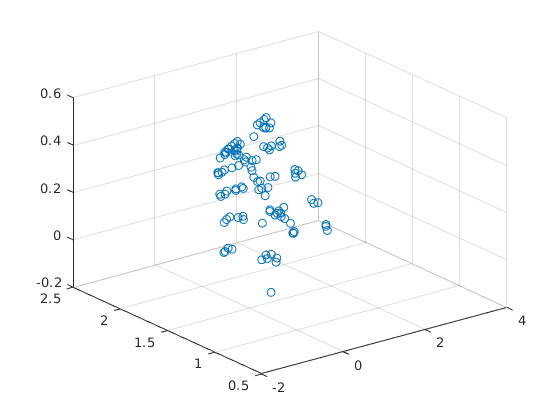

scatter3(ptCloudOut.Location(:,1),ptCloudOut.Location(:,2),ptCloudOut.Location(:,3))

## 2D delanay

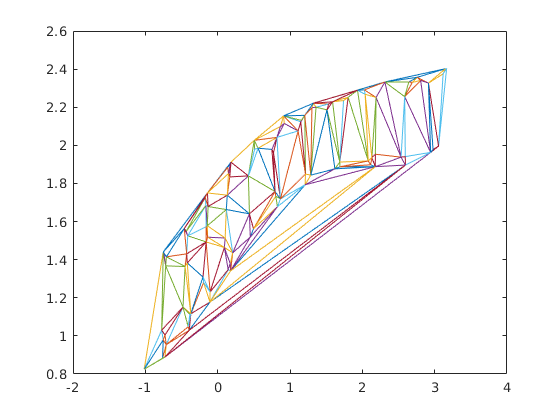

tri2d = delaunayTriangulation(ptCloudOut.Location(:,1),ptCloudOut.Location(:,2));
trimesh(tri2d.ConnectivityList, ptCloudOut.Location(:,1),ptCloudOut.Location(:,2))

## 3D delanay

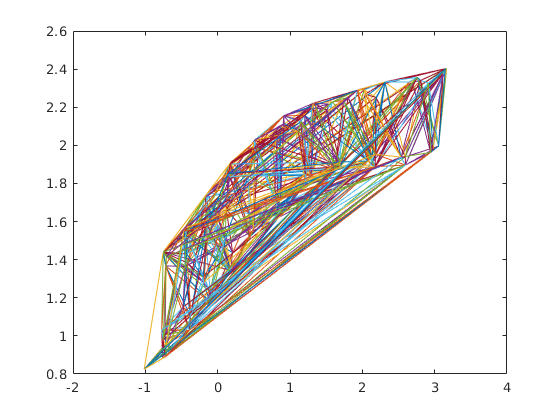

tri3d = delaunayTriangulation(ptCloudOut.Location(:,1),ptCloudOut.Location(:,2),ptCloudOut.Location(:,3));
trimesh(tri3d.ConnectivityList, ptCloudOut.Location(:,1),ptCloudOut.Location(:,2))

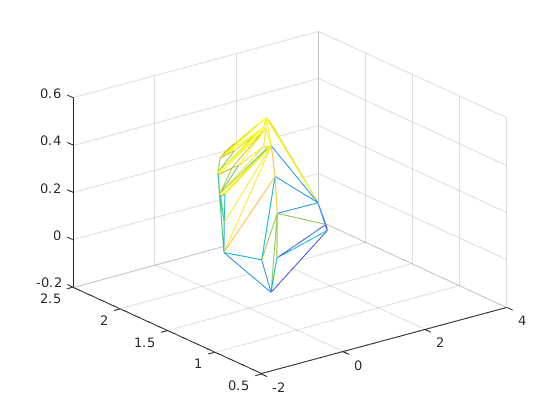

[C,v] = convexHull(tri3d);
figure
trimesh(C, ptCloudOut.Location(:,1),ptCloudOut.Location(:,2),ptCloudOut.Location(:,3))

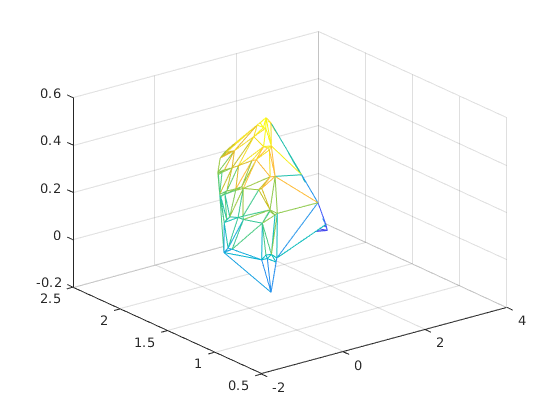

figure
trimesh(tri2d.ConnectivityList, ptCloudOut.Location(:,1),ptCloudOut.Location(:,2),ptCloudOut.Location(:,3))